# Trajectories

Frequently we want to define a smooth sequence of positions (or poses) from one point to another.  

Copyright (C) 1993-2017, by Peter I. Corke, [http://www.petercorke.com](http://www.petercorke.com)

First consider the 1-dimensional case. We define the start and end position

p0 = -1;
p1 = 2;

and a smooth path from p0 to p1 in 50 time steps is given by

p = tpoly(p0, p1, 50);
about p

p [double] : 50x1 (400 bytes)


which we see has 50 rows.  We can plot this 

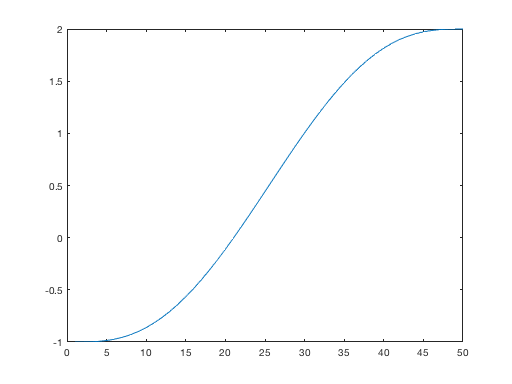

plot(p)

and see that it does indeed move smoothly from p0 to p1 and that the initial and final derivative (and second derivative) is zero.

We can also get the velocity and acceleration

[p,pd,pdd] = tpoly(p0, p1, 50);
subplot(3,1,1); plot(p); xlabel('Time'); ylabel('p');
subplot(3,1,2); plot(pd); xlabel('Time'); ylabel('pd');
subplot(3,1,3); plot(pdd); xlabel('Time'); ylabel('pdd');

This path is a 5th order polynomial and it suffers from the disadvantage that the velocity is mostly below the maximum possible value.  An alternative is

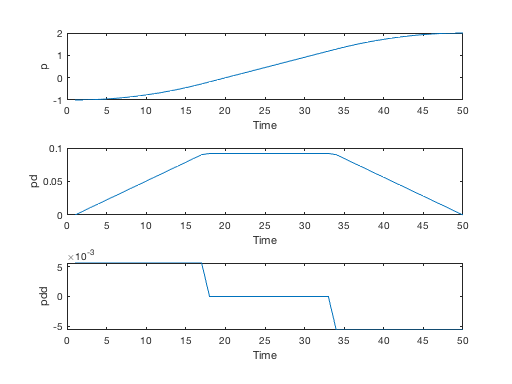

[p,pd,pdd] = lspb(p0, p1, 50);
subplot(3,1,1); plot(p); xlabel('Time'); ylabel('p');
subplot(3,1,2); plot(pd); xlabel('Time'); ylabel('pd');
subplot(3,1,3); plot(pdd); xlabel('Time'); ylabel('pdd');

which we see has a trapezoidal velocity profile.

Frequently the start and end values are vectors, not scalars, perhaps a 3D position or Euler angles.  In this case we apply the scalar trajectory function to a vector with

p = mtraj(@tpoly, [0 1 2], [2 1 0], 50);
about p

p [double] : 50x3 (1.2 kB)


and p again has one row per time step, and one column per vector dimension

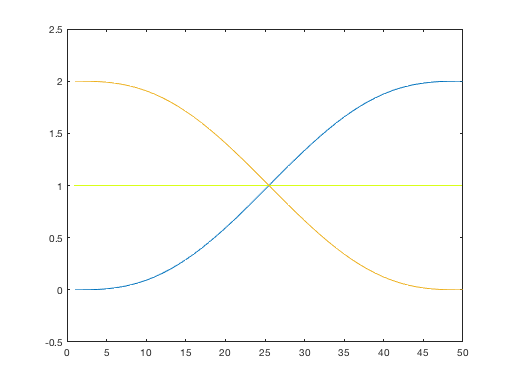

clf; plot(p)

Finally, we may wish to interpolate poses.  We will define a start and end pose

T0 = transl(0.4, 0.2, 0) * trotx(pi);
T1 = transl(-0.4, -0.2, 0.3) * troty(pi/2) * trotz(-pi/2);


and a smooth sequence between them in 50 steps is

T = ctraj(T0, T1, 50);
about T

T [double] : 4x4x50 (6.4 kB)


which is a 4x4x50 matrix.  The first pose is

T(:,:,1)

ans =     1.0000         0         0    0.4000
         0   -1.0000         0    0.2000
         0         0   -1.0000         0
         0         0         0    1.0000


and the 10th pose is

T(:,:,10)

ans =     0.9666    0.1972   -0.1638    0.3393
    0.1638   -0.9666   -0.1972    0.1696
   -0.1972    0.1638   -0.9666    0.0228
         0         0         0    1.0000


We can plot the motion of this coordinate frame by

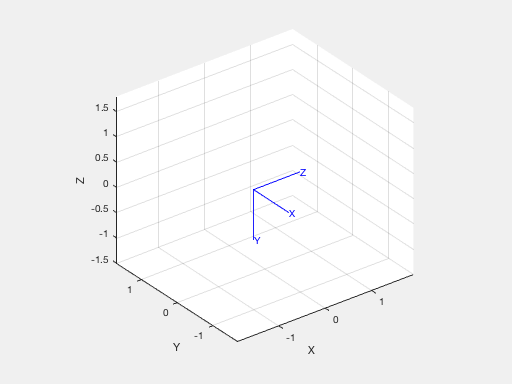

clf; tranimate(T)

We can do pose interpolation using SE3 objects rather than 4x4 matrices.  We will define a start and end pose

T0 = SE3(0.4, 0.2, 0) * SE3.Rx(pi);
T1 = SE3(-0.4, -0.2, 0.3) * SE3.Ry(pi/2) * SE3.Rz(-pi/2);


and a smooth sequence between them in 50 steps is

T = ctraj(T0, T1, 50);
about T

T [SE3] : 1x50 (6.4 kB)


which is an array of 50 SE3 objects.  The first pose is

T(1)

 

ans = 
         1         0         0       0.4
         0        -1         0       0.2
         0         0        -1         0
         0         0         0         1


and the 10th pose is

T(10)

 

ans = 
    0.9666    0.1972   -0.1638    0.3393
    0.1638   -0.9666   -0.1972    0.1696
   -0.1972    0.1638   -0.9666   0.02277
         0         0         0         1


We can plot the motion of this coordinate frame by

clf; tranimate(T)